clear all;
close all;
rosshutdown;

Shutting down global node /matlab_global_node_79745 with NodeURI http://darnel-VirtualBox:33445/



clc;
rosinit;

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
Initializing global node /matlab_global_node_96009 with NodeURI http://darnel-VirtualBox:34691/


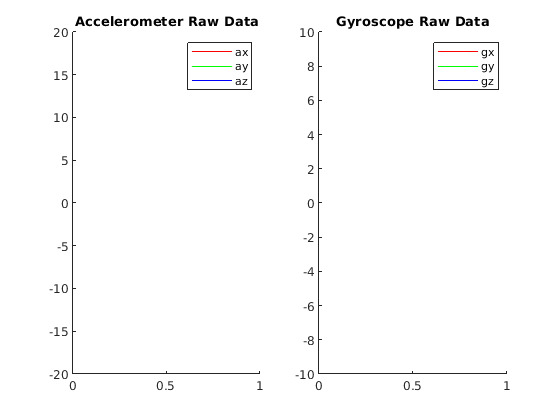


global h_imu_ax h_imu_ay h_imu_az;
global h_imu_gx h_imu_gy h_imu_gz;

global reset;

if (isempty(reset))
    reset = true;
end

f1 = figure();
% Configure accerlation raw plot
subplot(1,2,1);
h_imu_ax = animatedline('Color','r','MaximumNumPoints',120);
h_imu_ay = animatedline('Color','g','MaximumNumPoints',120);
h_imu_az = animatedline('Color','b','MaximumNumPoints',120);
axis tight
axis([-inf,inf,-20,20]);
title('Accelerometer Raw Data');
legend('ax','ay','az');

% Configure gyroscope raw plot
subplot(1,2,2);
h_imu_gx = animatedline('Color','r','MaximumNumPoints',120);
h_imu_gy = animatedline('Color','g','MaximumNumPoints',120);
h_imu_gz = animatedline('Color','b','MaximumNumPoints',120);
axis tight
axis([-inf,inf,-10,10]);
title('Gyroscope Raw Data');
legend('gx','gy','gz');


% Figure for attitude visualisation
% global f2;
% f2 = figure();
% axis([-10,10,-10,10,-10,10]);


% Register ROS subscriber callback
imu_sub = rossubscriber('/imu0', 'sensor_msgs/Imu' ,@imu_callback);


while true
    pause(1);
    reset = false;
    input()
end

Error using input
Not enough input arguments.

rosshutdown;



function imu_callback(src, msg)
    persistent time_offset;
    persistent last_t;
    global h_imu_ax h_imu_ay h_imu_az;
    global h_imu_gx h_imu_gy h_imu_gz;
%     global f2;
    
    time = msg.Header.Stamp.Sec + msg.Header.Stamp.Nsec / 1.0e9;
    
    if isempty(time_offset)
        time_offset = time;
        last_t = time;
    end
    
    % relative time
    t = time - time_offset;
    
    addpoints(h_imu_ax,t,msg.LinearAcceleration.X);
    addpoints(h_imu_ay,t,msg.LinearAcceleration.Y);
    addpoints(h_imu_az,t,msg.LinearAcceleration.Z);
    
    addpoints(h_imu_gx,t,msg.AngularVelocity.X);
    addpoints(h_imu_gy,t,msg.AngularVelocity.Y);
    addpoints(h_imu_gz,t,msg.AngularVelocity.Z);

    
    if (t > last_t)
        quat = [msg.Orientation.W, msg.Orientation.X, msg.Orientation.Y, msg.Orientation.Z];
        accel = [msg.LinearAcceleration.X msg.LinearAcceleration.Y msg.LinearAcceleration.Z]';
        gyro = [msg.AngularVelocity.X msg.AngularVelocity.Y msg.AngularVelocity.Z]';
        delta_t = t - last_t;
        
        naiveIntegrate(accel, gyro, quat, t, delta_t);
    end
    
    drawnow limitrate
    
    last_t = t;
 end

